# Dynamic Structural Econometrics - CCP estimation

Prepared by [Aaron Barkley, University of Melbourne](https://sites.google.com/site/aaronmbarkley)

*Disclaimer:* This file has been written with an emphasis on clarity. In particular, this means that (i) the file is completely self-contained in the sense that all necessary functions are defined within the file (as opposed to be stored as separate .m files) and (ii) code has not been optimized for performance. 

## The random utility model

We begin by reviewing the random utility model introduced in McFadden (1974, 1981). This model features many of the components we will use in considering dynamic discrete choice models, including discrete choices (binary in our case), logistic regression, and so on.

Consider an individual decision maker deciding whether to make a binary decision. For example, suppose an individual is moving across the United States to take a new job. They are planning to drive their car to their new city and sell the car when they get there. However, the current mileage on the car indicates that the car might break down before completing the long trip to the new city. The question facing the individual is whether or not to sell/trade in their car before they leave and obtain a more reliable car.

- Utility that is additively separable in observed state $x$ and idiosyncratic utility term $\epsilon$. Let $U_1$ denote the utility from selling the current car. We represent this utility as


$$U_1(x, \epsilon) = u_1(x) + \epsilon_1
$$


- Normalizing the deterministic component of utility for one choice to zero. In this case, we let $u_0(x)=0$ for all $x$ so that  $U_0 =  \epsilon_0$. 

- The idiosyncratic utility draws are iid from the same distribution: $\epsilon_0, \epsilon_1 \sim$Type I Extreme Value. In particular, this means that $\epsilon_1 - \epsilon_0$ follows a Logistic distribution, so that Pr$\big(U_1(x,\epsilon_1) > U_0(x,\epsilon)\big) = \frac{\exp(u_1(x) - u_0(x))}{1+\exp(u_1(x) - u_0(x))}$, the familiar logistic probability.

- Finally, we assume that the utility from selling the car $u_1(x)$ is linear in the observed mileage: $u_1(x) = \theta_0 + \theta_1 x$, where $\theta_0$ represents the monetary benefit to the individual from not having to obtain a new, more reliable car and $\theta_1 x$ is the expected cost of repairs if the car breaks down before reaching the destination.

Suppose we observe a set of decisions from $N$ individuals about whether or not to take the trip with the current car. If $d_n=0$, the car was replaced for individual $n$, and if $d_n=1$, then the car was kept. 


$$\mathcal{L}_n(x_n)=\Big( \frac{\exp(u_1(x_n) - u_0(x_n)) }{1+\exp(u_1(x_n) - u_0(x_n))} \Big)^{d_n} \times \Big( \frac{1 }{1+\exp(u_1(x_n) - u_0(x_n))} \Big)^{1-d_n} $$


Taking the log and plugging in $u_0(x)=0$ and $u_1(x) = \theta_0 + \theta_1 x$ gives the log-likelihood associated with observation $n$:


$$\ell_n(x_n) = 1\{d_n=1\} \times(\theta_0 + \theta_1 x_n) - \log(1+\exp(\theta_0 + \theta_1 x_n))$$


Maximizing the log-likelihood with respect to the parameters $\theta$ conditional on the observed decisions and car mileages $\{d_n, x_n\}_{n=1}^N$ will generate the structural estimates. The code below simulates some sample data and estimates this model.

rng(2023);
theta=[5; -2]; % Utility parameters
Nobs=1000; % Number of observations
x=2.5+0.5*randn([Nobs,1]); % State variables
x=round(x,1);
[~,x_ind]=ismember(x,unique(x)); % Encoded states -- we'll explain this below
X=unique(x);
x_len=length(X);
ChoiceProb= exp([ones(Nobs,1), x]*theta)./(1+exp([ones(Nobs,1), x]*theta)); % Logit choice probabilities
p=rand([Nobs,1]);
d=(p<ChoiceProb); % Simulate choices with uniform random draws.

% Now estimate with the logit log-likelihood
lik_fun = @(theta) -sum((d==1).*([ones(Nobs,1), x]*theta) - log(1+exp([ones(Nobs,1), x]*theta)));
[theta_hat,~]=fminunc(lik_fun,[0;1],optimoptions('fminunc','Display','none'));
RUM_estimates = table(theta_hat,theta,'VariableNames',{'Logit estimates','True values'})

RUM_estimates = 2×2 table
    Logit estimates    True values
    _______________    ___________

         4.9067             5     
        -1.9544            -2     


#### Moving from static to dynamic

Suppose that each individual was not making a one-off decision about replacing the car. For simplicity, suppose that they anticipate moving *again* within the next two years, and expect to have to make the same decision about whether or not to replace their car for something more reliable at that time. (For example, the individual is a recent economics PhD graduate who is taking a two year postdoc, and expects that at the end of the postdoc they will have to move again.) Each individual is rationally forward looking, and so will anticipate how obtaining a more reliable car now might help them with moving to a new city again in a few years. 

Suppose we ignore this dynamic feature of the decision-making process when we estimate the model, and assume that the consumers are making one-off decisions as in the case above. What happens to our estimates? (Ignore the specific details about the data generation in the code below -- we will cover this later!)


emc=double(eulergamma);
beta=0.9;
ChoiceProb2=exp([ones(x_len,1), X]*theta)./(1+exp([ones(x_len,1), X]*theta));
test_ind_1=((1:x_len)+min(5,x_len-(1:x_len)))';
test_ind_2=repmat(5,[x_len,1]);
v2=[ones(x_len,1), X]*theta + beta*(emc-log(ChoiceProb2(test_ind_1)));
v1=beta*(emc-log(ChoiceProb2(test_ind_2)));
ChoiceProb1=exp(v2-v1)./(1+exp(v2-v1));
p1=p; 
p2=rand([Nobs,1]);
d1=(p1<ChoiceProb1(x_ind));
x2=5.*(1-d1) + d1.*test_ind_1(x_ind);
[~,x2_ind]=ismember(x2,(1:max(x_ind))');
d2=(p2<ChoiceProb2(x2_ind));

lik_fun = @(theta) -sum((d1==1).*([ones(Nobs,1), x]*theta) - log(1+exp([ones(Nobs,1), x]*theta)));

[theta_hat_static,~]=fminunc(lik_fun,[0;1],optimoptions('fminunc','Display','none'));
Static_estimates = table(theta_hat_static,theta,'VariableNames',{'Logit "static" estimates','True values'})

Static_estimates = 2×2 table
    Logit "static" estimates    True values
    ________________________    ___________

              2.9049                 5     
            -0.70613                -2     


As we can see from the above table, the estimates are now significantly biased. Assuming a static model when the model is dynamic and consumers are forward-looking will lead to incorrect inferences about preferences! If we fix this and account for dynamics, we get the correct estimates. (Again, ignore the implementation details -- this will get covered in the next section.)


lik_fun2= @(theta) -sum((d1==1).*([ones(Nobs,1), x]*theta + beta*(emc-log(ChoiceProb2(test_ind_1(x_ind))))-beta*(emc-log(ChoiceProb2(test_ind_2(x_ind))))) ...
    - log(1+exp([ones(Nobs,1), x]*theta + beta*(emc-log(ChoiceProb2(test_ind_1(x_ind))))-beta*(emc-log(ChoiceProb2(test_ind_2(x_ind)))))));
[theta_hat_dynamic,~]=fminunc(lik_fun2,[0;1],optimoptions('fminunc','Display','none'));
Dynamic_estimates = table(theta_hat_dynamic,theta,'VariableNames',{'Logit dynamic estimates','True values'})

Dynamic_estimates = 2×2 table
    Logit dynamic estimates    True values
    _______________________    ___________

            4.9651                  5     
            -1.992                 -2     


## Bus engine replacement 

We now consider the problem of Harold Zurcher studied in Rust (1987). Zurcher maintains a fleet of buses. Maintenance on the buses becomes more costly as the bus engines accumulate mileage. Replacing the engines effectively resets the mileage on the bus and lowers the maintenance cost; however, replacing the engines is much more costly than a single maintenance. The problem facing Zurcher is to decide *when* to replace the engines: replacing the engines too early generates high costs through expensive engine replacements, while waiting too long means that maintenance becomes excessively costly over the long term.

We assume that, as in Rust (1987), we have monthly data on bus maintenance records. This includes data on a set of buses $\mathcal{N} = \{1,...,N\}$ over $T$ months. The observations include mileage readings $x_t$ for each bus and and indicator $d_t$ for whether the engine has been replaced.

### Model

- Time is discrete, with $t=1,2,...,\overline{T}$ denoting each period, with $\overline{T} = \infty$.

- Each period, Harold Zurcher chooses between two actions. He can either replace the bus engine, $d_{1t}=1$, or not replace $d_{2t}=1$. These are mutually exclusive, so that $d_{1t} + d_{2t} = 1$.

- Zurcher's payoff depends on a single state variable $x_t$ that represents the mileage of the bus. Mileage advances by a random amount if the bus engine is not replaced and is set to zero if the bus engine is replaced. Denote by $f_d(x_{t+1} | x_t)$ the distribution over next period mileage conditional on current mileage after making choice $d$. When the bus engine is replaced, mileage resets to zero, so that $f_1(x_1 | x_t)=1$ for all $x_t$. Mileage accumulation when the engine is not replaced follows a discrete analog of the exponential distribution up to some maximum mileage $\overline{x}$ where mileage increment is $\Delta_x$.


$$f_2(x_{t+1} | x_t) = \begin{cases} \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big) & \mbox{ for } \ d_{t}=2 \ \mbox{ and } \ x_t \leq x_{t+1} \leq \overline{x}, \\ \exp\big(-(\overline{x} - x_t)\big) & \mbox{ for } \ x_{t+1}>=\overline{x},  \\ 0 & \mbox {otherwise.} \end{cases}$$


- In addition to mileage $x_t$, there is a permanent and observable bus-specific type $s \in \{1,..,S\}$. Assume that the deterministic component of flow payoffs for each action $j=1,2$ for a bus of type $s$ are given by


$$u_{1t}  =  0$$



$$u_{2t}  =   \theta_1 + \theta_2 x_t + \theta_3 s$$


- Payoffs also have an additively separable idiosyncratic component $\epsilon_{jt}$ so that the total flow payoff from choice $j$ in period $t$ is $u_{jt}(x_t) + \epsilon_{jt}$. We assume that $\epsilon_{jt}$ are i.i.d draws from a  Type I EV distribution.

- Let $z_t \equiv (x_t, s)$ denote the time-varying state variable $x_t$ together with the permanent bus type $s$.

- Denoting the optimal decision rule at $t$ by $d^o_t(z_t, \epsilon_t) = [d^o_{1t}(z_t,\epsilon_{1t}), \ d^o_{2t}(z_t,\epsilon_{2t})]$, we define the ex-ante value function for state $x_t$ in period $t$ as


$$V_t(z_t) \equiv E \Big\{\sum_{\tau=t}^{\overline{T}} \sum_{j=1}^2 \beta^{\tau - t - 1} d^o_{jt}(z_{\tau} \epsilon_{\tau}) (u_{j\tau}(z_{\tau}) + \epsilon_{j\tau})  \Big\}$$


- The conditional value function $v_{jt}(z_t)$ is the value function for choice $j$ in period $t$ and state $x_t$ less the utility shock $\epsilon_{jt}$. In the case of Zurcher's bus engine replacement problem, these functions can be expressed as 


$$v_{1}(z_t) = \beta \sum_{x=1}^{\overline{x}} V(x,s) f_1(x \ | x_{t+1})$$



$$v_{2}(z_t) = \theta_1 + \theta_2x_t + \theta_3 s + \beta \sum_{x=1}^{\overline{x}} V(x,s) f_1(x \ | x_{t+1})$$


where we have "undone" the combination of $x_t$ and $s$ in the state variable to make clear that the state transition function $f$ only affects mileage accumulation and not the permanent bus type $s$.

- Note that all $t$ subscripts have been removed from value functions and state transitions: this is a stationary, infinite horizon problem.

- In the binary choice setting with Type I EV preference shocks we can express conditional choice probabilities very simply:


$$p_2(z_t) = \mbox{Pr}(v_2(z_t) + \epsilon_{2t} \geq v_1(z_t) + \epsilon_{1t}) \ = \ \mbox{Pr}\big(\epsilon_{1t} - \epsilon_{2t} \leq v_2(z_t) - v_1(z_t)\big) \ = \ \frac{\exp\Big(v_2(z_t) - v_1(z_t)\Big)}{ 1 + \exp\Big(v_2(z_t) - v_1(z_t))\Big)}$$


- Representation: finally, we can use the results of Hotz and Miller (1993) to express the difference between the value function $V_t(z_t)$ and conditional value function $v_{j}(z_t)$:


$$V(z_t) - v_{j}(z_t) = \psi_j(p(z_t)), \quad$$
 

where $\quad \psi_j(p(z_t)) = \gamma - \log(p_j(z_t))$ when $\epsilon_{ijt} \sim$ Type I EV, where $\gamma \approx 0.577$ is the Euler-Mascheroni constant. 

#### Representation and identification

The mapping between the difference conditional value functions and the conditional choice probabilities $v_j(x_t) - v_k(x_t) = \psi_k(p(x_t)) -\psi_j(p(x_t))$ forms the basis for representation and identification. To generate the conditions that establish identification, we use the restrictions imposed on the utility function. In our case, we have assumed that $u_1(x)=0$ for all states $x \in X$. Define $\kappa_{\tau}$ as the distribution over state variables reached after $\tau - t$ periods with respect to the choice sequence $\{d^*_{jt}\}$. For simplicity, assume for now that there is only a single bus type $s$, so that we can effectively ignore this state variable and express states and transitions only in terms of bus mileage $s$. The distribution over period $\tau$ states $x_{\tau}$ is expressed as


$$\kappa_{\tau}(x_{\tau +1} | x_t, j) = \begin{cases} f_{j}(x_{t+1} | x_t) & \mbox{if } \ \tau=t+1 \\ \sum_{x_{\tau} \in X} \sum_{k\in \{1,2\}} d^*_{k\tau} \ f_k(x_{\tau+1} | x_{\tau})\kappa_{\tau-1}(x_{\tau} | x_t, j)  & \mbox{otherwise.} \end{cases}$$


In our setting, we will define $d^*_{1\tau} = 1$, i.e., the reference choice in each period is to replace the engine. Repeated application of $v_j(x_t) - v_k(x_t) = \psi_k(p(x_t)) -\psi_j(p(x_t))$ using replacement as the reference choice in each period $\tau \geq t+1$generates that 


$$u_2(x_t) = \psi_1(x_t) - \psi_2(p(x_t)) \\ \qquad \quad + \sum_{\tau = t+1}^T \sum_{x_\tau \in X} \beta^{\tau - t} \psi_1(x_{\tau})\left[ \kappa_{\tau-1}(x_{\tau} | x_t, 1) - \kappa_{\tau-1} (x_{\tau} | x_t, 2) \right]$$


This equation establishes identification of $u_2(x)$ for each $x \in X$: everything on the right-hand side is known ($\psi(\cdot), \ \beta$) or can be estimated ($p(\cdot), \kappa(\cdot | \cdot)$). It is useful to "stack" the moment condition equations for each state $x$ and express the moment conditions in matrix form. 


$$\mathbf{u}_j = \left[ \begin{array}{c} u_j(x_1) \\ \vdots \\ u_j(x_X) \end{array} \right], \qquad F_j = \left[ \begin{array}{c c c} f_j(x_1 | x_1) & \cdots & f_j(x_X | x_1) \\ \vdots & \ddots & \vdots \\ f_j(x_X | x_1)  & \cdots & f_j(x_X | x_X) \end{array} \right], \qquad \Psi_{j} = \left[ \begin{array}{c} \psi_j(p(x_1)) \\ \vdots \\ \psi_j(p(x_X)) \end{array} \right]$$


#### Two ways to develop an estimator.

With this matrix representation, we can write the moment conditions in matrix form in two ways that permit straightforward estimation.

**1. Using the unrestricted utilities.**


$$\mathbf{u}_2 = \Psi_1 - \Psi_2 + \mathbf{u}_1 + \beta (F_1 - F_2)(\Psi_1 + \mathbf{u}_1) +\sum_{\tau = t+2}^T \beta^{\tau - t+1} F_1(\Psi_1 + \mathbf{u}_1)$$


When $T = \infty$, we can use the matrix version of geometric series convergence to express the utility as:


$$\mathbf{u}_2 = \Psi_1 - \Psi_2 +\mathbf{u}_1 + \beta \Big(F_1 - F_2 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1 + \mathbf{u}_1\Big)$$


Note that everything on the right-hand side is known (utilities, $\beta$, transition matrices) or can be estimated ($\psi_1, \psi_2$).

**2. Using the differenced conditional value functions. **

Recall that if we can express $v_2(x) - v_1(x)$ in terms of the parameters $\theta$, then we can use the logit estimator directly. While we can derive an expression directly from the representation identity, it is easiest to work from the unrestricted utility estimates above.


$$\mathbf{v}_2 - \mathbf{v}_1 =  \mathbf{\Psi}_1 - \mathbf{\Psi}_2\qquad  \Rightarrow  \\
\mathbf{v}_2 - \mathbf{v}_1 = \mathbf{u}_2 -\mathbf{u}_1 + \beta \Big(F_2 - F_1 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1 + \mathbf{u}_1\Big)$$


This form allows us to use the logit estimator: $u_2$ is a known function of the structural parameter vector $\theta$, and everything else is known or can be estimated.

**(3. Bonus method: using the ex-ante value function)**

We can also express the ex-ante value function with this type of matrix representation (see Arcidiacono and Ellickson (2011) for additional discussion):


$$\overline{V} = \left( I - \beta \sum_d (\mathbf{p}_d \lambda)*F_d \right)^{-1} \left( \sum_d \mathbf{p}_d*[\mathbf{u}_d + \Psi_d] \right)$$


where $*$ is element-wise multiplication, $\mathbf{p}_d$ is the $X \times 1$ vector of choice probabilities for choice $d$ and $\lambda$ is an $1\times X$ vector of ones.

Methods 1 and 2 above are especially useful when both (i) $u_2$ is linear in $\theta$ and (ii) $u_1(x) = 0$ for all $x$. In settings without these assumptions, Method 3 using parameters from both utility functions $u_1$ and $u_2$ may be a more practical way to represent the value function. Note that the second term in parentheses above is simply the probability that each choice is optimal $p_d$ multiplied by the expected utility conditional on that choice being the optimal choice $u_d + \psi_d$ for each possible choice $d$. 

### Data

clc; clear
rng(19);

%x_min = 0.0 ; x_max = 15.0; 
%delta_x = 0.05;
x_min = 0.0 ; x_max = 18.0; 
delta_x = 0.9;
x_len = (x_max-x_min)/delta_x+1;

We have set $\overline{x} = 18$ and $\Delta_x = 0.9$. With mileage starting at zero, there are 21 state values.

format shortG
x = linspace(x_min, x_max, x_len);
StatesTable = table((1:10)',x(1:10)','VariableNames',{'State index (encoded state)','State value'})

StatesTable = 10×2 table
    State index (encoded state)    State value
    ___________________________    ___________

                 1                       0    
                 2                     0.9    
                 3                     1.8    
                 4                     2.7    
                 5                     3.6    
                 6                     4.5    
                 7                     5.4    
                 8                     6.3    
                 9                     7.2    
                10                     8.1    


Knowing the state values is needed for calculating the flow payoffs $u_j(x)$, but for nearly every other calculation we are primarily interested in the state's index. We call this the **encoded state**: it maps value associated with a state to that state's number. For example, in the representation above, the encoded state of mileage = 0.2 is 5. (*Note that this will change slightly below when we add the bus types to the state variable.*)

Calculating the probability of transitioning from one state to another requires referring to the relevant row and column indices in the state transition matrix $f$. Recall that $f_2(x_{t+1} | x_t) =  \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big)$ for $x_{t+1} \leq 18$. We can define the state transition matrix in two steps. First, we assign the probabilities for each state $x<18$, and then we lump all of the leftover probability from mileage larger than $18
$ into the last state.

x_tday = repmat(x, [x_len,1]);
x_next = x_tday';                                      
f = (x_next >= x_tday)' .* exp(- (x_next - x_tday)') .* (1 - exp(-delta_x)); 
f(:,end) = 1 - sum(f(:,1:(end-1)), 2); % The last column is set so that the sum of probs is 1
F = cumsum(f(:,:), 2);

F2=f;
F1=zeros(size(f));
F1(:,1)=1;
emc = double(eulergamma);
F2(1:10,1:10)

ans =       0.59343      0.24127     0.098093     0.039882     0.016215    0.0065924    0.0026803    0.0010897   0.00044305   0.00018013
            0      0.59343      0.24127     0.098093     0.039882     0.016215    0.0065924    0.0026803    0.0010897   0.00044305
            0            0      0.59343      0.24127     0.098093     0.039882     0.016215    0.0065924    0.0026803    0.0010897
            0            0            0      0.59343      0.24127     0.098093     0.039882     0.016215    0.0065924    0.0026803
            0            0            0            0      0.59343      0.24127     0.098093     0.039882     0.016215    0.0065924
            0            0            0            0            0      0.59343      0.24127     0.098093     0.039882     0.016215
            0            0            0            0            0            0      0.59343      0.24127     0.098093     0.039882
            0            0            0            0            0            

Defined in this way, each row $i$ of $f$ corresponds to the probability distribution over states conditional on state $i$. The first row is the distribution over next period states conditional on the bus engine having a mileage of zero. The probability of remaining at zero is $\mbox{Pr}(x_{t+1} = 0 | x_t = 0) = f_2(1,1) = 0.59343$, the probability of mileage increasing to state 2 is $\mbox{Pr}(x_{t+1} = 0.5 | x_t = 0) = f_2(1,2) = 0.24127$, and so on. All elements below the diagonal are zero because the bus mileage cannot decrease without replacing the engine.

We assume that the replacement decision resets mileage to zero and that the bus cannot accumulate any mileage in this period (i.e., the act of replacing the engine takes the entire period and no driving can occur for that bus).


$$F_1 = \left( \begin{array} {c c c} 1 & 0 & 0 \\ 1 & 0 & 0 \\ \vdots & \vdots & \vdots \\ 1 & 0 & 0 \end{array} \right)$$


**Data generation**

We use the following parameters and data settings to simulate the data, where $\pi$ is the fraction of buses that have $s=1$:


$$\beta = 0.9, \quad \theta = \left(\begin{array}{c} 2 \\ -0.15 \\ 1 \end{array} \right), \quad T=15, \quad N=2,000, \quad S=\{1,2\}, \quad \pi = 0.4$$$


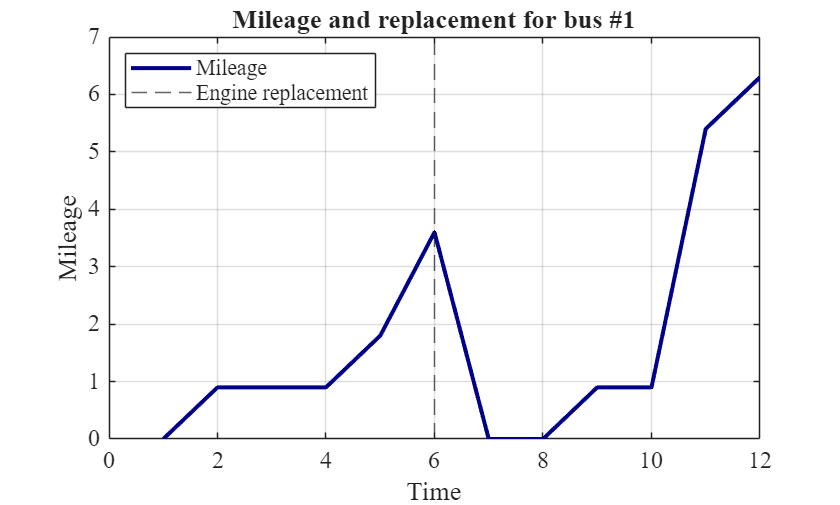

beta = 0.9;
theta = [2.00, -0.15, 1.0];
T=15;
S=1:2;
X=x;
N=1000;
pi=0.4; 
[data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, f, F, X,beta, pi, theta);


plot(data_t(1,1:12), data_x(1,1:12)); 
xline(data_t(1,data_d(1,1:12)==1),'--');
%xline(7,'--');
xlabel('Time'); ylabel('Mileage');title('Mileage and replacement for bus #1');
legend('Mileage','Engine replacement','location','northwest');


% Optional: save data
%Data_vars={'data_t', 'data_x', 'data_s', 'data_d', 'data_x_index'};
%Const_vars={'beta','theta','S','X','x_len','pi','T','x','N','f','F','F1','F2','emc'};
%All_vars=[Data_vars, Const_vars];
%save("Bus_engine_ccp_data.mat",All_vars{:});

### CCP estimation

The CCP estimation routine has three steps.

**(i) Estimating the conditional choice probabilities**

Our first step is to estimate the conditional choice probabilities. We can obtain the maximum likehood estimates by a simple frequency estimator:


$$\hat{p}_j(x) = \frac{\sum_{n=1}^N \sum_{t=1}^T \mathbf{1}\{x_{nt}=x, \ d_{jnt} = 1\}}{\sum_{n=1}^N \sum_{t=1}^T \mathbf{1}\{x_{nt}=x\}}$$


% Optional: load data
%load("Bus_engine_ccp_data.mat");

ccp_hat = zeros(length(X),length(S));
epsilon=1e-4;
for j=1:length(X)
    for s=1:length(S)
        ccp_hat(j,s) = sum(data_d(data_x_index(:)==j & data_s(:)==s)==1)/sum(data_x_index(:)==j & data_s(:)==s);
    end
end
never_reached=isnan(ccp_hat(:)); % keep track of states that never occur in the data
ccp_hat=max(epsilon, min(1-epsilon,ccp_hat)); % Makes sure that all probabilities are in the open interval (0,1), as "1" and "0" observations cause problems.


In practice, it is common to use a parametric first-stage and estimate the conditional choice probabilities with a flexible parametric or semi-parametric form. Here we use a logit with quadratic and interaction terms to estimate the conditional choice probabilities.


$$X^{logit}_{nt} = [1, \ x_{nt}, \ x_{nt}^2, \ \mathbf{1}\{s_{nt}=1\}, \ x_{nt}\mathbf{1}\{s_{nt}=1\}] \\
p^{logit} = \frac{\exp(X^{logit}\lambda)}{1+\exp(X^{logit}\lambda))}$$


Remember, the goal at this stage is *choice prediction* using the *observed states*. Many different estimators can be used in this first stage. The primary objective is that capture how states predict choices as accurately as possible. We estimate $\lambda$ using the parametric representation above and then use $\hat{\lambda}$ to generate fitted values for the conditional choice probabilities.

start_est=tic;
X_logit=[data_x(:) data_x(:).^2 (data_s(:)==2) (data_s(:)==2).*data_x(:)]';
lambda_hat = mnrfit(X_logit',data_d(:));

ccp_hat_logit=zeros(length(X),length(S));

for s=1:length(S)
    X_logit_fit=[X', X'.^2, (s==2)*ones(size(X,2),1), (s==2).*X' ];
    temp_ccps=mnrval(lambda_hat,X_logit_fit);
    ccp_hat_logit(:,s)=temp_ccps(:,1);
end

ccp_hat = ccp_hat_logit;

% Compare with true CCPs
[~,~,ccps_true] = value_function_iteration(S,F2,X, beta,theta);

%figure(1);subplot(1,2,1);h=heatmap(1-ccp_hat(1:20,:));
%h.Title='Estimates for non-replacement p_2';h.XLabel = 'Bus type s'; h.YLabel='Mileage state index';
%subplot(1,2,2);h2=heatmap(1-ccps_true(1:20,:));
%h2.Title='True p_2';h2.XLabel = 'Bus type s'; h2.YLabel='Mileage state index';

*Combining states: *to have fewer expressions to work with, we will combine the two states, mileage and bus type, into a single state variable ($\texttt{all\_states}$) and work with this object. 

all_states = [X', ones(length(X),1); X', 2*ones(length(X),1)];
ccp_tot=ccp_hat(:);
F1_tot=[F1, zeros(x_len); zeros(x_len), F1];
F2_tot=[F2, zeros(x_len); zeros(x_len), F2];
[~, x_s_index]=ismember( [data_x(:), data_s(:)], all_states, 'rows');

num_states = size(all_states,1);

- The variable $\texttt{x\_s\_index}$ is the ***encoded state*** of each observation in the data. It maps each observation to a row of the $\texttt{all\_states}$ matrix.

- The matrix $\texttt{F1\_tot}$ and $\texttt{F2\_tot}$ are the combined state transitions for all states (all mileage states plus the two observed bus types). These are constructed by blocks of zeros and the original state transition matrices $F_1, F_2$ because bus types cannot change: a "type 2" bus will always be a "type 2" bus, so all probabilities associated with "type 1" bus states are zeros.

**(ii) Calculate the future value term**


$$\mathbf{v}_2 - \mathbf{v}_1 = \mathbf{u}_2  + \underbrace{\beta \Big(F_2 - F_1 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1\Big)}_{\text{'BigV\_diff'}}$$


BigV_diff = beta*(F2_tot - F1_tot)*((eye(num_states) - beta*F1_tot)\(emc-log(ccp_tot)));


**(iii) Estimate **$\theta$** using the logit representation**

Recalling that $\mathbf{u}_2 = [1, X, S]\times \theta$, it is straightforward to define the log-likelihood function. This is similar to the log-likelihood for the static random utility model; the difference is that there is a *state-specific offset term* (our "BigV_diff") applied to each observation ("BigV_est"). 

X_logit_struct = [ones(num_states,1) all_states];

X_est = X_logit_struct(x_s_index,:); % Get the state variables associated with each observation
BigV_est = BigV_diff(x_s_index); % Get the BigV_diff term associated with each observation

% Log-likelihood: like static case, but with a constant "BigV" term for each state:
lik_fun = @(theta) -sum((data_d(:)==2).*(X_est*theta + BigV_est) - log(1+exp(X_est*theta + BigV_est)));
[theta_hat_ccp,fval_ccp]=fminunc(lik_fun,[1,1,1]');


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


LogitCCPEstimatesTable = table(theta_hat_ccp,theta','VariableNames',{'Logit CCP estimates','True values'})

LogitCCPEstimatesTable = 3×2 table
    Logit CCP estimates    True values
    ___________________    ___________

           2.0027                 2   
         -0.15967             -0.15   
          0.97811                 1   


The table above shows that the estimated values are quite similar to the true values and can be generated with two logistic regressions and a few calculations.

### Full-information maximum likelihood estimation 

For reference, we also include a full information maximum likelihood estimation routine based on the nested fixed point. This version is simple to code but computationally very slow; however, it gives a sense of how close the CCPs estimate are to a fully efficient benchmark.

fiml_start=tic;
fiml_fun = @(theta) FIML_log_likelihood(theta,data_x,data_s,data_d,X,S,data_x_index,f,beta);

theta_0=0.1*ones(3,1);
options = optimoptions('fminunc','Display','none');
[theta_hat,~] = fminunc(fiml_fun,theta_0,options);
FIML_EstimatesTable = table(theta_hat,theta','VariableNames',{'FIML estimates','True values'})

FIML_EstimatesTable = 3×2 table
    FIML estimates    True values
    ______________    ___________

         2.0643              2   
       -0.15989          -0.15   
        0.98411              1   


fiml_time=toc(fiml_start)

fiml_time =       0.31592


### Exercise: using the unrestricted utility estimates directly

**Defining the estimator**

This estimator follows the moment condition formulation above, using the unrestricted utility estimates to develop a minimum distance estimator (Altug and Miller (1998)).

We estimate the unrestricted utility of not replacing the engine for each state according to

    $\mathbf{u}_2 = \Psi_1 - \Psi_2 -\mathbf{u}_1 + \beta \Big(F_1 - F_2 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1 + \mathbf{u}_1\Big)$, 

where $\Psi_1 = \left( \begin{array}{c} \gamma - \log(p_1(x^1)) \\ \vdots \\ \gamma - \log(p_1(x^M)) \end{array} \right)$, $\quad \Psi_2 = \left( \begin{array}{c} \gamma - \log(p_2(x^1)) \\ \vdots \\ \gamma - \log(p_2(x^M)) \end{array} \right)$, $\mathbf{u}_1$ is an $M \times 1$ vector of zeros, and $\mathbf{u}_2$ is an $M \times 1$ vector of utilities for choice 2.

Finally, we define a weighting matrix $W$ and estimate the parameters so as to minimize the weighted squared deviation. 


$$\hat{\theta}_{MD} = \arg \min_{\theta} \Big[ \mathbf{u}_2(\mathbf{x};\theta) - \hat{\mathbf{u}}_2\Big]' W \Big[ \mathbf{u}_2(\mathbf{x};\theta) - \hat{\mathbf{u}}_2\Big]$$


where $\mathbf{u}_2(\mathbf{x};\theta) = \left(\begin{array}{c} u_2(x^1;\theta) \\ \vdots \\ u_2(\overline{x};\theta) \end{array} \right)$ and $\mathbf{\hat{u}}_2 = \left(\begin{array}{c} \hat{u}_2(x^1) \\ \vdots \\ \hat{u}_2(\overline{x}) \end{array} \right)$ are vectors of the utilities associated with each state. 

**Exercise: **Implement this estimator using the estimated conditional choice probabilities from the previous sections. Use the identity matrix as a weighting matrix. When you construct the estimator, use one moment condition for each observation; that is, you should use the $\texttt{x\_s\_index}$ variable to "copy" moment conditions corresponding to the number of times they appear in the data. You should estimate $\theta$ using an OLS estimator.

% Exercise code here


### (Bonus: Method 3. Stationary representation of the *ex-ante value* function.)

Recall from above that, using a similar derivation as the unrestricted utility estimates from Section 1.2, we can express the ex-ante value function in terms of the flow utility, state transition probabilities, and $\Psi$ terms (see Arcidiacono and Ellickson (2011) for details):


$$\overline{V} = \left( I - \beta \sum_d (\mathbf{p}_d \lambda)*F_d \right)^{-1} \left( \sum_d \mathbf{p}_d*[\mathbf{u}_d + \Psi_d] \right)$$


where $*$ is element-wise multiplication, $\mathbf{p}_d$ is the $X \times 1$ vector of choice probabilities for choice $d$ and $\lambda$ is an $1\times X$ vector of ones. The relevant term for evaluating the logit likelihood is $\mathbf{v}_2 - \mathbf{v}_1$, which we can express as


$$\mathbf{v}_2 - \mathbf{v}_1 = \mathbf{u}_2 - \mathbf{u}_1 + \beta (F_2 - F_1) \overline{V}$$


with the above expression for $\overline{V}$, we can now have an expression for the differenced conditional value function that we can use in the logit likelihood. 

Now we are ready to begin construction of the estimator. One of the advantages of the CCP approach is that we can perform many of these calculations outside of the optimization routine, reducing the number of calculations that need to be conducted for each optimization iteration.

To simplify the representation, we construct the components of the ex-ante value function $\overline{V}$ in pieces. We start with the term $\left( I - \beta \sum_d (\mathbf{p}_d \lambda)*F_d \right)$, which we define as

V1=(eye(size(all_states,1))-beta*(repmat(ccp_tot,[1,length(all_states)]).*F1_tot + repmat(1-ccp_tot,[1,length(all_states)]).*F2_tot));

Next, we define $\sum_d \mathbf{p}_d * \Psi_d$:

V2=(ccp_tot.*(emc-log(ccp_tot))+(1-ccp_tot).*(emc - log(1-ccp_tot)));

Finally, we have $\sum_d \mathbf{p}_d *\mathbf{u}_d$. Recalling that $\mathbf{u}_1 = 0$, we can express this as $\mathbf{p}_2 *(X \theta')$. We're going to leave off the $\theta$ term for now, as this will be the main argument in the optimization function:

V3=((1-ccp_tot).*[ones(length(all_states),1) all_states]);

Finally, we write the optimization function (see "ccp_stationary_likelihood" below) and define the likelihood function inline using the inputs we created above:


temp_lik=@(theta) ccp_stationary_likelihood(theta, data_d, F1_tot, F2_tot,x_s_index,all_states,beta,V1,V2,V3);
[theta_hat_stationary,fval]=fminunc(temp_lik,[1,1,1]');


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


est_time=toc(start_est)

est_time =        1.2722


StationaryCCPEstimatesTable = table(theta_hat_stationary,theta','VariableNames',{'Stationary CCP estimates','True values'})

StationaryCCPEstimatesTable = 3×2 table
    Stationary CCP estimates    True values
    ________________________    ___________

              2.0607                   2   
            -0.15926               -0.15   
             0.98427                   1   


## Functions

### Stationary CCP likelihood function

function [lik]=ccp_stationary_likelihood(theta, data_d, F1_tot, F2_tot,x_s_index,all_states,beta,V1,V2,V3)


We first "re-assemble" the pieces we defined above. The value defined below is 


$$\overline{V} = \left( I - \beta \sum_d (\mathbf{p}_d \lambda)*F_d \right)^{-1} \left( \sum_d \mathbf{p}_d*[\mathbf{u}_d+\Psi_d]\right) $$


V_exante=V1\(V2+V3*theta); % Using the "slash" notation for matrix inverse multiplication as recommended by Matlab.

Finally, we use the ex-ante value function to evaluate the differenced conditional value function for each observation in the sample. We use the "x_s_index" variable, which maps each state observation into an index for one of the 602 state variables, to do this in one step.

v_diff =[ones(size(x_s_index,1),1) all_states(x_s_index,:)]*theta + beta*(F2_tot(x_s_index,:)-F1_tot(x_s_index,:))*V_exante;
lik=-sum((data_d(:)==2).*(v_diff) - log(1+exp(v_diff)));
end

### Data generation

function [data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, x_tran, x_tran_cumul, X, beta,pi,theta)
    
    initial_run=5; % We start the state variables at zero and let the model run for five periods before we start sampling
    x_index = ones(N, T+initial_run); 
    x_sim = zeros(N,T+initial_run);
    
    s_sim  = (rand(N,1) > pi) + 1;
    d_sim  = zeros(N, T+initial_run); 
    draw_ccp = rand(N, T+initial_run);
    draw_x  = rand(N, T+initial_run);

    value_function = value_function_iteration(S,x_tran,X,beta, theta);
    for n = 1:N
        for t = 1:T+initial_run
            % j=1 replace 
            u1 = 0.0;
            v1 = u1 + beta*value_function(1,s_sim(n)); % Reset to zero mileage deterministically if engine is replaced.
            % j=2 is continue
            u2 = theta(1) + theta(2) * X(x_index(n,t)) + theta(3) * s_sim(n);
            v2 = u2 + beta* x_tran(x_index(n,t),:)*value_function(:,s_sim(n));
            
            % Conditional choice probability
            p1 = exp(v1)/(exp(v1)+exp(v2)); 

            % Simulate next period
            d_sim(n,t)    = (draw_ccp(n,t) > p1) + 1; % 1: replace, 2: continue
            x_index(n,t+1) = (d_sim(n,t)==2) * sum((draw_x(n,t) > x_tran_cumul(x_index(n,t),:))) + 1; 
            x_sim(n,t+1) = X(x_index(n,t+1));
        end
    end
    
    data_x = x_sim(:, initial_run+1:T+initial_run);
    data_d = d_sim(:, initial_run+1:T+initial_run);
    data_s = repmat(s_sim,  [1,T]);
    data_t = repmat(transpose(1:T), [1,N])';
    [~, data_x_index] = ismember(data_x,X); 
    
    return 

end


### Full-information maximum likelihood

function [fiml_lik] = FIML_log_likelihood(theta,data_x,data_s,data_d,X,S,data_x_index,x_tran,beta)

value_function = value_function_iteration(S,x_tran,X,beta,theta);

D_temp = data_d(:);
S_temp = data_s(:);
X_index_temp = data_x_index(:);

v1 = repmat(beta*value_function(1,S),[length(X),1]);
v2 = theta(1) + theta(2)*X' + theta(3)*S + beta*(x_tran(:,:)*value_function(:,:));

x_s_index    = sub2ind(size(v2), X_index_temp, S_temp);
fiml_lik = -sum((D_temp==2).*(v2(x_s_index)-v1(x_s_index)) - log(1+exp(v2(x_s_index)-v1(x_s_index))));

end

### Value function iteration

function [value_function,value_diff,ccps] = value_function_iteration(S,x_tran,X, beta,theta)
x_len = length(unique(X));
emc = double(eulergamma);
value_function_2 = zeros(x_len,length(S));
ccps=zeros(x_len,length(S));
value_diff=1;
max_iter=1000;
iter=1;
while value_diff>1e-5 && iter < max_iter
    value_function_1 = value_function_2;
    for s=1:length(S)
                v1 = repmat(beta*value_function_1(1,s),[x_len,1]);
                v2=theta(1) + theta(2)*X' + theta(3)*s + beta*(x_tran(:,:)*value_function_1(:,s));
                value_function_2(:,s) = log(exp(v1)+exp(v2)) + emc;
                ccps(:,s)=1./(1+exp(v2-v1));
    end
    iter=iter+1;
    value_diff = max(max((value_function_2 - value_function_1).^2));
end
value_function = value_function_2;
end


## References

Abbring, J. H., & Daljord, Ø. (2020). [Identifying the discount factor in dynamic discrete choice models](https://www.econometricsociety.org/publications/quantitative-economics/2020/05/01/Identifying-the-discount-factor-in-dynamic-discrete-choice-models). *Quantitative Economics*, *11*(2), 471-501.

Altuğ, S., & Miller, R. A. (1998). [The effect of work experience on female wages and labour supply](http://www.comlabgames.com/ramiller/effect_workexp_femaleWage_laborSupply1998.pdf). *The Review of Economic Studies*, *65*(1), 45-85.

Arcidiacono, P., & Ellickson, P. B. (2011). [Practical methods for estimation of dynamic discrete choice models](https://www.researchgate.net/profile/Paul-Ellickson/publication/228313050_Practical_Methods_for_Estimation_of_Dynamic_Discrete_Choice_Models/links/0912f50db1b686c65a000000/Practical-Methods-for-Estimation-of-Dynamic-Discrete-Choice-Models.pdf). *Annu. Rev. Econ.*, *3*(1), 363-394.

Arcidiacono, P., & Miller, R. A. (2011). [Conditional choice probability estimation of dynamic discrete choice models with unobserved heterogeneity](http://public.econ.duke.edu/~psarcidi/ccp0810.pdf). *Econometrica*, *79*(6), 1823-1867.

Caoui, E. H., Hollenbeck, B., & Osborne, M. (2022). [The Impact of Dollar Store Expansion on Local Market Structure and Food Access](https://elhadicaoui.github.io/files/dollarstores.pdf). Working paper.

Kalouptsidi, M., Scott, P. T., & Souza-Rodrigues, E. (2021).[ Linear IV regression estimators for structural dynamic discrete choice models.](https://www.nber.org/system/files/working_papers/w25134/w25134.pdf) *Journal of Econometrics*, *222*(1), 778-804.

Keane, M. P., & Wolpin, K. I. (1997). [The career decisions of young men](https://www.researchgate.net/profile/Michael-Keane-8/publication/24103974_The_Career_Decisions_of_Young_Men/links/09e415074aada5b3b7000000/The-Career-Decisions-of-Young-Men.pdf). *Journal of political Economy*, *105*(3), 473-522.

Magnac, T., & Thesmar, D. (2002). [Identifying dynamic discrete decision processes](https://editorialexpress.com/jrust/econ615/readings/magnac_thesmar_econometrica_2002.pdf). *Econometrica*, *70*(2), 801-816.

McFadden, D. (1981). [Econometric Models of Probabilistic Choice.](http://www.its.caltech.edu/~mshum/gradio/McFaddenChapter1981.pdf) *Structural analysis of discrete data with econometric applications*, *198272*.

Rust, J. (1987). [Optimal replacement of GMC bus engines: An empirical model of Harold Zurcher](https://editorialexpress.com/jrust/crest_lectures/zurcher.pdf). *Econometrica: Journal of the Econometric Society*, 999-1033.